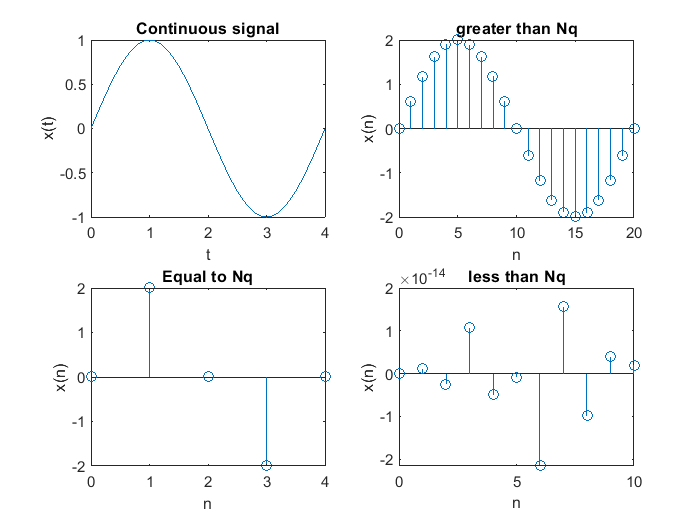

clc;
T=0.04; % Time period of 50 Hz signal
t=0:0.0005:0.02;
f = 1/T;
n1=0:40;
size(n1);
xa_t=sin(2*pi*2*t/T);
subplot(2,2,1);
plot(200*t,xa_t);
title('Verification of sampling theorem');
title('Continuous signal');
xlabel('t');
ylabel('x(t)');
ts1=0.002;%>niq rate
ts2=0.01;%=niq rate
ts3=0.1;%<niq rate
n=0:20;
x_ts1=2*sin(2*pi*n*ts1/T);
subplot(2,2,2);
stem(n,x_ts1);
title('greater than Nq');
xlabel('n');
ylabel('x(n)');
n=0:4;
x_ts2=2*sin(2*pi*n*ts2/T);
subplot(2,2,3);
stem(n,x_ts2);
title('Equal to Nq');
xlabel('n');
ylabel('x(n)');
n=0:10;
x_ts3=2*sin(2*pi*n*ts3/T);
subplot(2,2,4);
stem(n,x_ts3);
title('less than Nq');
xlabel('n');
ylabel('x(n)')